%ROC for rawdata and CNN
testing = imageDatastore(fullfile([pwd filesep 'rawTest' filesep 'data' filesep]),...
     'IncludeSubfolders',true,...
    'LabelSource','foldernames');
augimgsTesting = augmentedImageDatastore([227 227],testing);

[Pred2, scores] = classify(trainedSN, augimgsTesting);

## plot ROCs

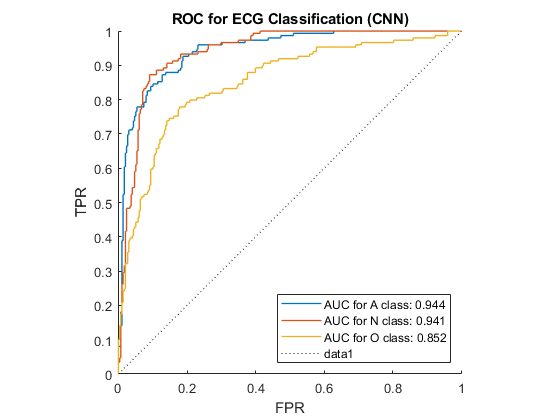

classNames = {'A','N','O'};
hold on
for i=1:3
    [xr, yr, ~, auc] = perfcurve(testing.Labels,scores(:, i), classNames{i});
    plot(xr, yr, 'linewidth', 1)
    legends{i} = sprintf('AUC for %s class: %.3f', classNames{i}, auc);
end

legend(legends, 'location', 'southeast')
line([0 1], [0 1], 'linestyle', ':', 'color', 'k');
xlabel('FPR'), ylabel('TPR')
title('ROC for ECG Classification (CNN)')
axis square